clear

## **Lista de funções:**

r = @(x) 100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
g = @(x) x(1)*(x(1) + 3)*(x(1) - 3)*(x(1) - 5) + x(2)*(x(2) + 3)*(x(2) - 3)*(x(2) - 5);
f = @(x) ((x(1))^2 - 100)*((x(1))^2 - 61) + ((x(2))^2 - 25)*((x(2))^2 - 16) - 15*cos(x(1)-(7/5))*cos(x(2)-(9/2));
h = @(x) ((x(1))^2 - 100)*((x(1))^2 - 61) + ((x(2))^2 - 25)*((x(2))^2 - 16) - 15*sin(x(1)-(7/5))*sin(x(2)-(9/2));

## Teste 1 - Função matemática g(x)

disp("--------------- Variaveis globais --------------");

--------------- Variaveis globais --------------


Nvar = 2;
Nmax = randi([35,50])

Nmax = 36

errodf = 15e-2

errodf = 0.1500

NPontosIniciais = randi([8,13])

NPontosIniciais = 8

x_values=[-11;-11]; y_values=[7;7];

disp("------------------- Outputs -------------------");

------------------- Outputs -------------------



PontosIniciais = getNPontosIniciais(NPontosIniciais, Nvar, x_values, y_values);
tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_wolfe(g, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste1=toc

tempo_execucao_teste1 = 30.9075

xopt_teste1 = minGlobal(Lopt, g)

xopt_teste1 =    -1.8706
   -1.8706


taxa_media_convergencia_teste1 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste1 = 10

tipo_convergencia_teste1 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste1 = 'Convergência para um mínimo global'

[minimos_locais_teste1, minimizantes_locais_teste1] = minimosMinimizantesLocais(Lopt, g)

minimos_locais_teste1 =    -1.8706
   -1.8706


minimizantes_locais_teste1 = -141.3956

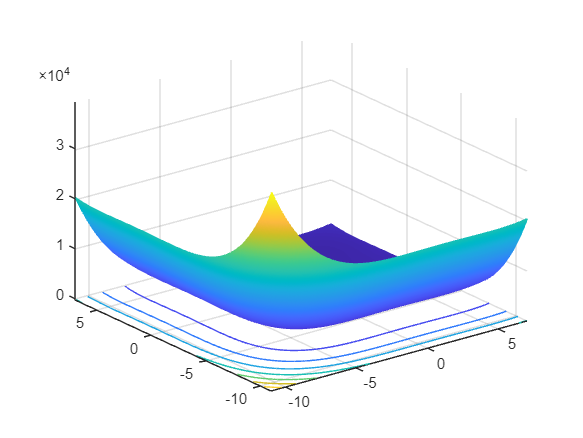

close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

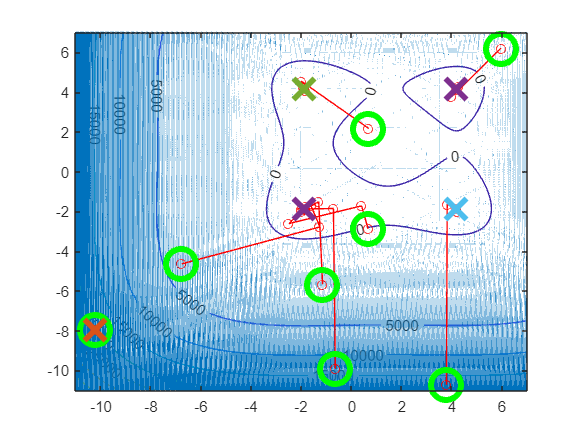


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 2- Função de Rosenbrock

disp("---------------------- // ----------------------")

---------------------- // ----------------------



tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_wolfe(r, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste2=toc

tempo_execucao_teste2 = 96.2460

xopt_teste2 = minGlobal(Lopt, r)

xopt_teste2 =     1.2919
    1.6694


taxa_media_convergencia_teste2 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste2 = 36

tipo_convergencia_teste2 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste2 = 'Convergência para um mínimo local'

[minimos_locais_teste2, minimizantes_locais_teste2] = minimosMinimizantesLocais(Lopt, r)

minimos_locais_teste2 =     0.6367    0.6912    1.2919
    0.4052    0.4751    1.6694


minimizantes_locais_teste2 =     0.1320    0.0961    0.0852


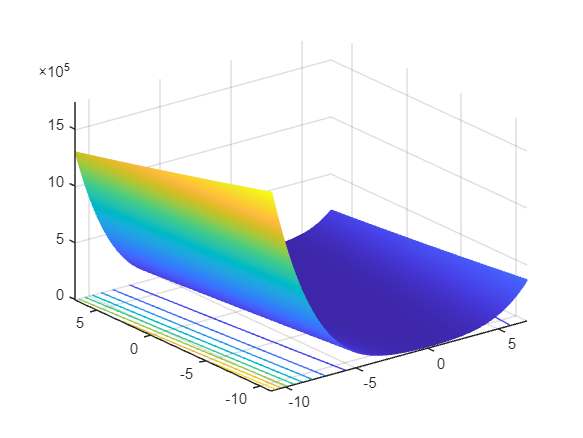

close all

nivelGraficos(r,x_values(1),y_values(1),x_values(2),y_values(2))

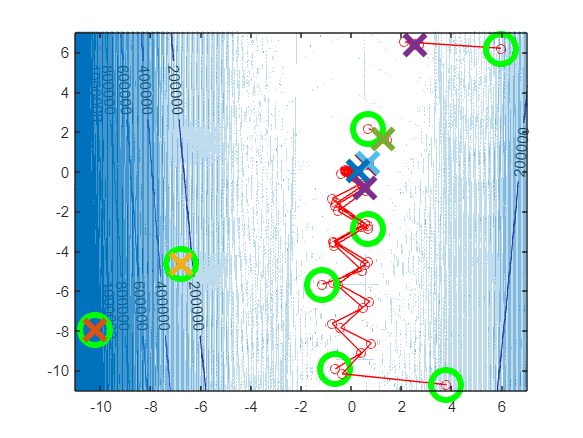


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 3- Função matemática f(x)

disp("---------------------- // ----------------------")

---------------------- // ----------------------



tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_wolfe(f, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste3= toc

tempo_execucao_teste3 = 38.3793

xopt_teste3 = minGlobal(Lopt, f)

xopt_teste3 =    -8.9547
   -4.5480


taxa_media_convergencia_teste3 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste3 = 18.1250

tipo_convergencia_teste3 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste3 = 'Convergência para um mínimo global'

[minimos_locais_teste3, minimizantes_locais_teste3] = minimosMinimizantesLocais(Lopt, f)

minimos_locais_teste3 =    -8.9546   -8.9547
   -4.5480   -4.5480


minimizantes_locais_teste3 =  -408.7072 -408.7072


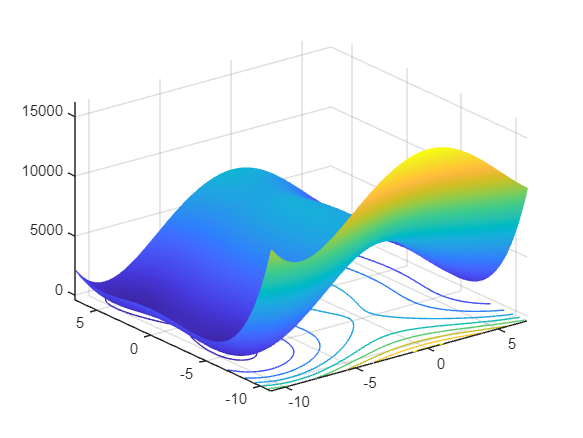

close all

nivelGraficos(f,x_values(1),y_values(1),x_values(2),y_values(2))

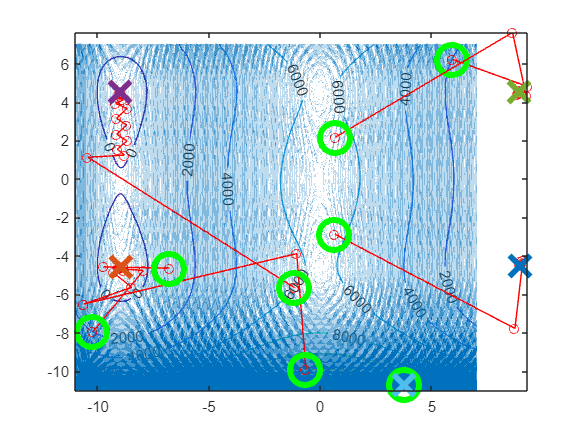


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 4 - Função matemática h(x,y)

disp("---------------------- // ----------------------")

---------------------- // ----------------------



tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_wolfe(h, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste4 = toc

tempo_execucao_teste4 = 37.6405

xopt_teste4 = minGlobal(Lopt, h)

xopt_teste4 =     8.9730
    4.6122


taxa_media_convergencia_teste4 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste4 = 17.6250

tipo_convergencia_teste4 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste4 = 'Convergência para um mínimo global'

[minimos_locais_teste4, minimizantes_locais_teste4] = minimosMinimizantesLocais(Lopt, f)

minimos_locais_teste4 =    -8.9676   -8.9679
   -4.5956   -4.5965


minimizantes_locais_teste4 =  -408.4486 -408.4386


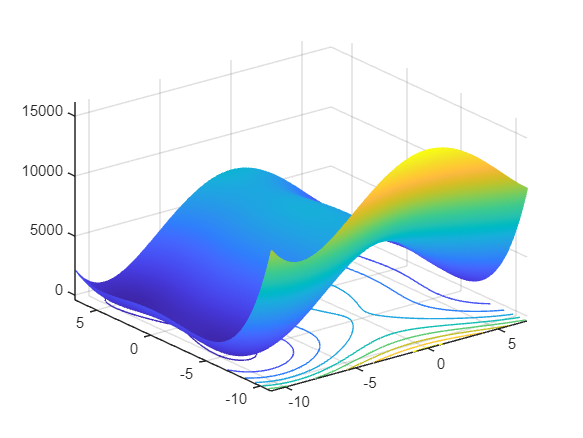

close all

nivelGraficos(h,x_values(1),y_values(1),x_values(2),y_values(2))

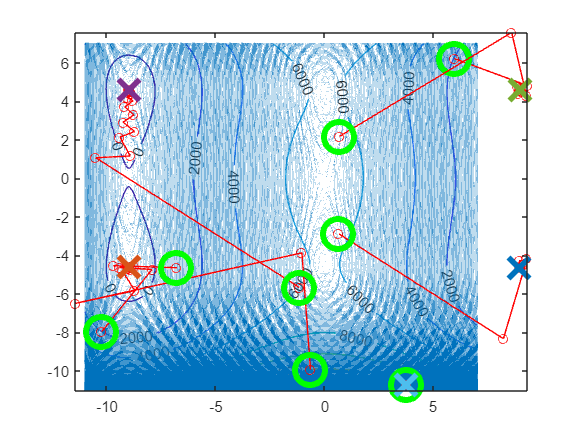


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

T = table([tempo_execucao_teste1; tempo_execucao_teste2; tempo_execucao_teste3;tempo_execucao_teste4], ...
          [taxa_media_convergencia_teste1; taxa_media_convergencia_teste2; taxa_media_convergencia_teste3; taxa_media_convergencia_teste4], ...
          {tipo_convergencia_teste1; tipo_convergencia_teste2; tipo_convergencia_teste3; tipo_convergencia_teste4}, ...
          'VariableNames', {'Tempo de Execucao', 'Taxa Media de Convergencia', 'Tipo de Convergencia'}, ...
          'RowNames', {'Teste1', 'Teste2', 'Teste3', 'Teste4'});

disp(T);

              Tempo de Execucao    Taxa Media de Convergencia             Tipo de Convergencia         
              _________________    __________________________    ______________________________________

    Teste1         30.908                        10              {'Convergência para um mínimo global'}
    Teste2         96.246                        36              {'Convergência para um mínimo local' }
    Teste3         38.379                    18.125              {'Convergência para um mínimo global'}
    Teste4         37.641                    17.625              {'Convergência para um mínimo global'}

